clc
clear
run ("Basics.m");

A =          0    1.0000         0         0
   -4.0000   -1.3000    1.3333    0.1300
         0         0         0    1.0000
    1.3333    1.3000   -2.6333   -2.6667


sys =
 
                  1.3 s + 1.333
  ---------------------------------------------
  s^4 + 3.967 s^3 + 9.931 s^2 + 12.18 s + 8.756
 
Continuous-time transfer function.


sysd =
 
  0.0004156 z^3 + 0.001144 z^2 - 0.000978 z - 0.0003017
  -----------------------------------------------------
      z^4 - 3.463 z^3 + 4.55 z^2 - 2.685 z + 0.601
 
Sample time: 0.12835 seconds
Discrete-time transfer function.



c =          0    0.0004    0.0011   -0.0010   -0.0003


d =     1.0000   -3.4634    4.5497   -2.6854    0.6010


### System identification

tic
tfinal=200;
t = 0:T_s:tfinal;
u = zeros(numel(t),1);

#### General Input+white Noise

u = gensig('sine' , tfinal , tfinal ,T_s);
Noise=-0.2+(0.2+0.2)*rand(numel(t),1);
u=u+Noise;

Out Put Generating

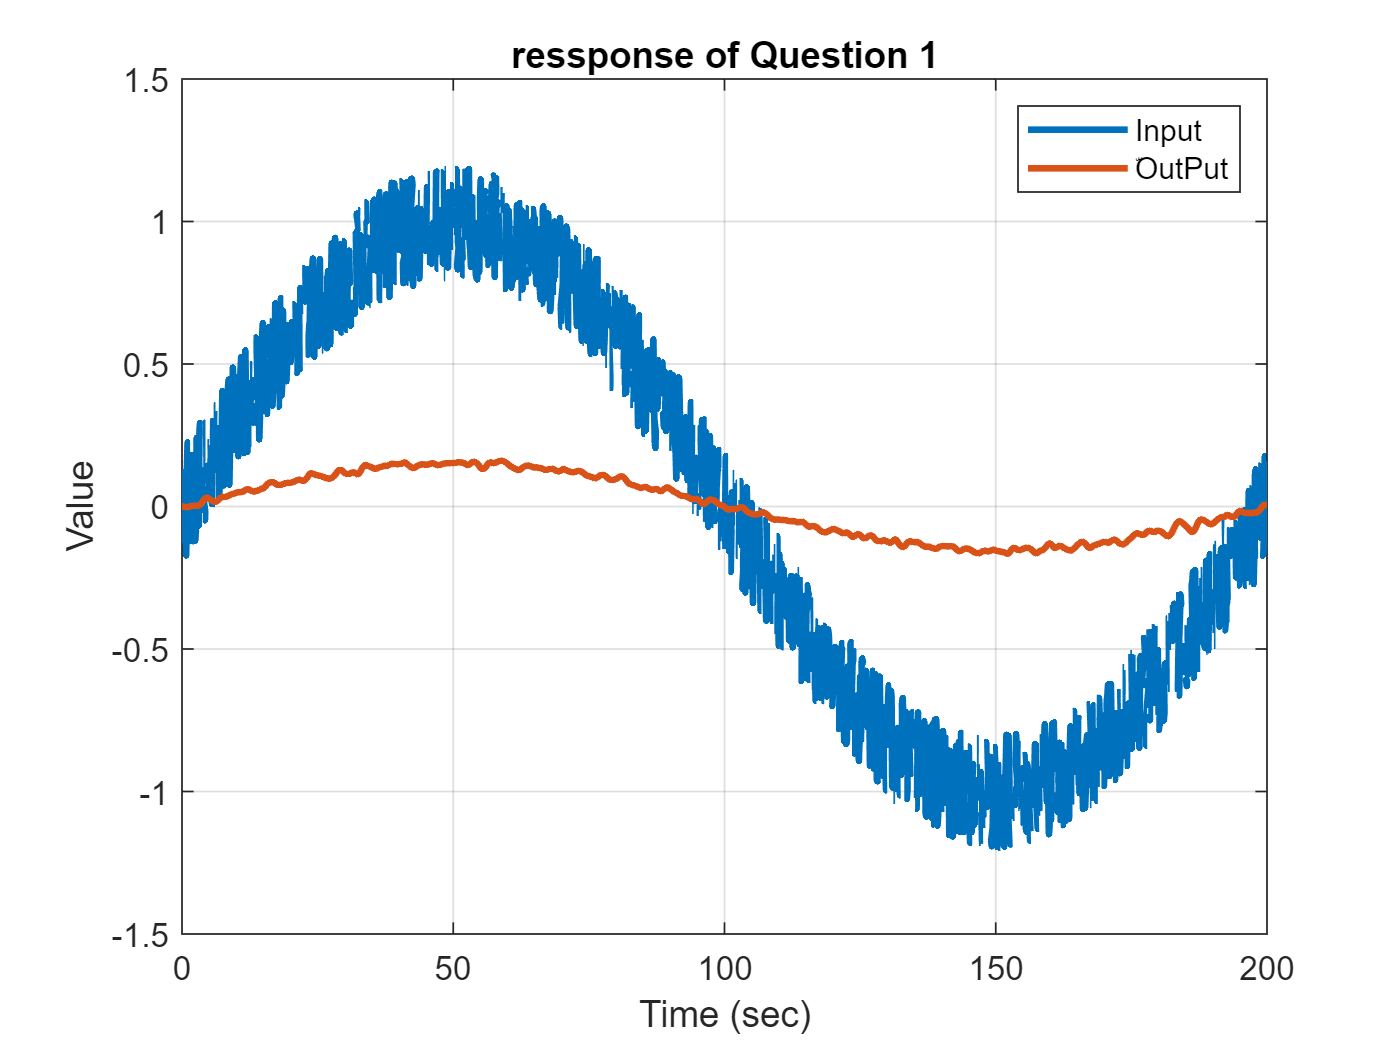

y = lsim(sysd  ,u ,t);
plot(t,u ,t , y ,'LineWidth',2) ;
xlabel('Time (sec)') ;
ylabel('Value') ;
title('ressponse of Question 1') ;
grid on
legend('Input' , 'ّOutPut') ;
xlim([0 200])

% ylim([-1.2 1.2])

## LS Identification

N = numel(y) ;
Parameters_in_den=3

Parameters_in_den = 3

Parameters_in_num=3

Parameters_in_num = 3

Nv=Parameters_in_num+Parameters_in_den

Nv = 6

phi=[];
for i=(max(Parameters_in_num,Parameters_in_den)+1):N
    phi(i,:) = [(y(i-1:-1:i-Parameters_in_den))' , (u(i-1:-1:i-Parameters_in_num))'];
end
theta_hat=((phi'*phi)^(-1))*(phi'*y)

theta_hat =     2.5336
   -2.1682
    0.6193
    0.0004
    0.0015
    0.0004


% norm([theta_hat]-[d,c(2:end)]')
% norm(Y-phi*theta_hat)
sysdd=tf(theta_hat((Parameters_in_num+1):end,end)' ,[1 -theta_hat(1:Parameters_in_num ,end)'], T_s)

sysdd =
 
  0.0004051 z^2 + 0.001516 z + 0.0004161
  --------------------------------------
    z^3 - 2.534 z^2 + 2.168 z - 0.6193
 
Sample time: 0.12835 seconds
Discrete-time transfer function.



### ‌BODE


ident_analog = d2c(sysdd)

ident_analog =
 
  0.000231 s^2 - 0.008031 s + 1.403
  ---------------------------------
  s^3 + 3.733 s^2 + 5.964 s + 9.206
 
Continuous-time transfer function.



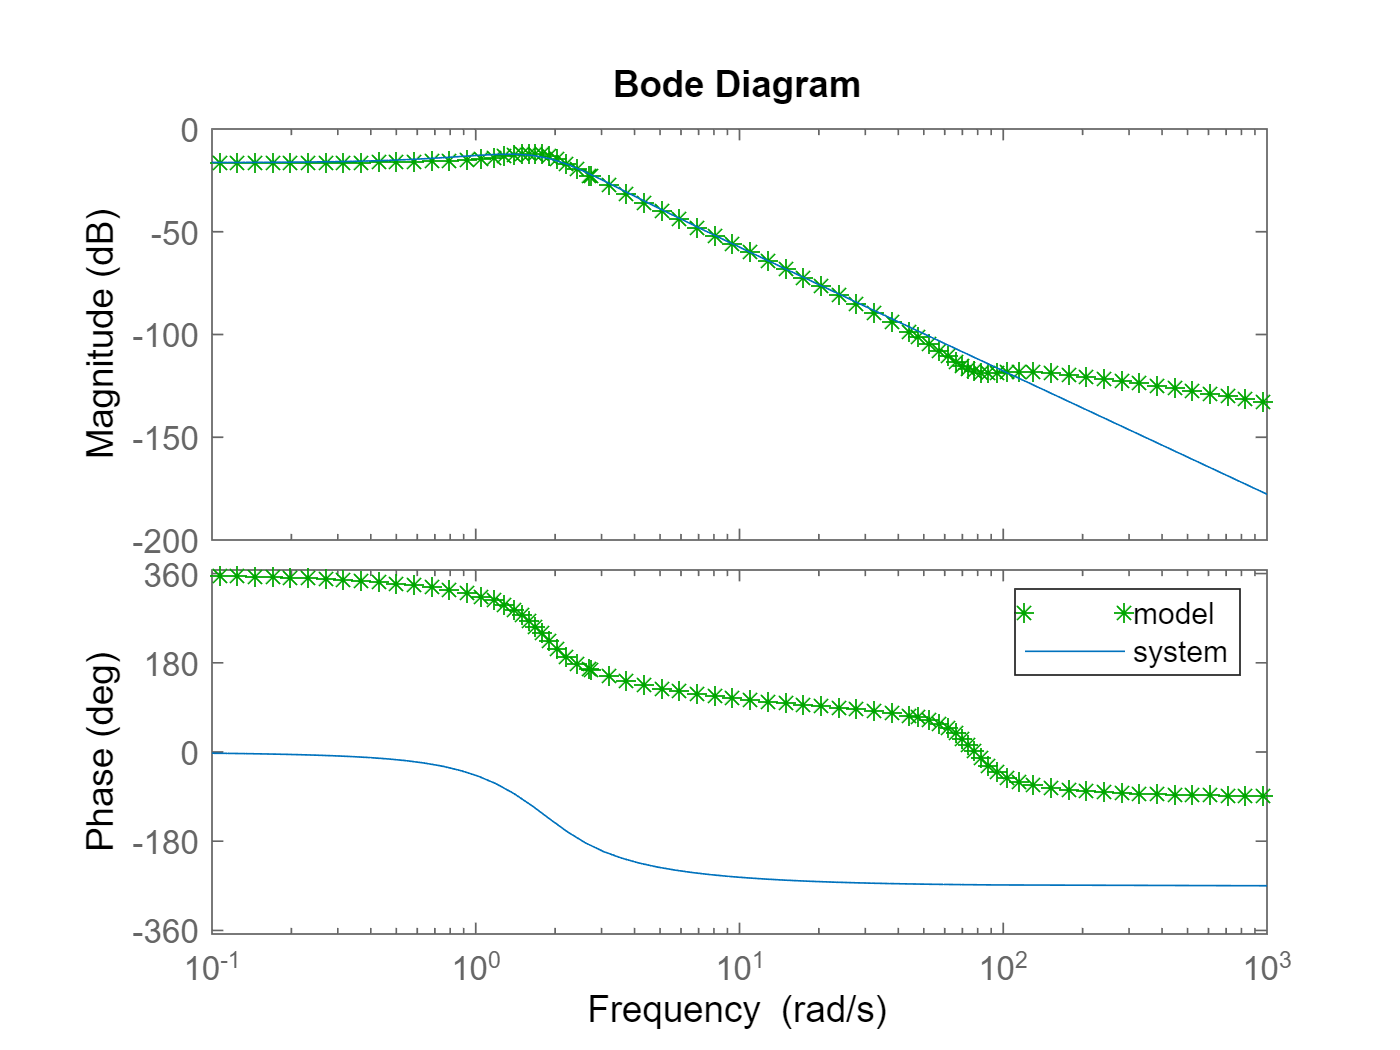

figure
bode(ident_analog ,'g*',sys )
legend('model','system')

### Ploting discret system and Least square Model

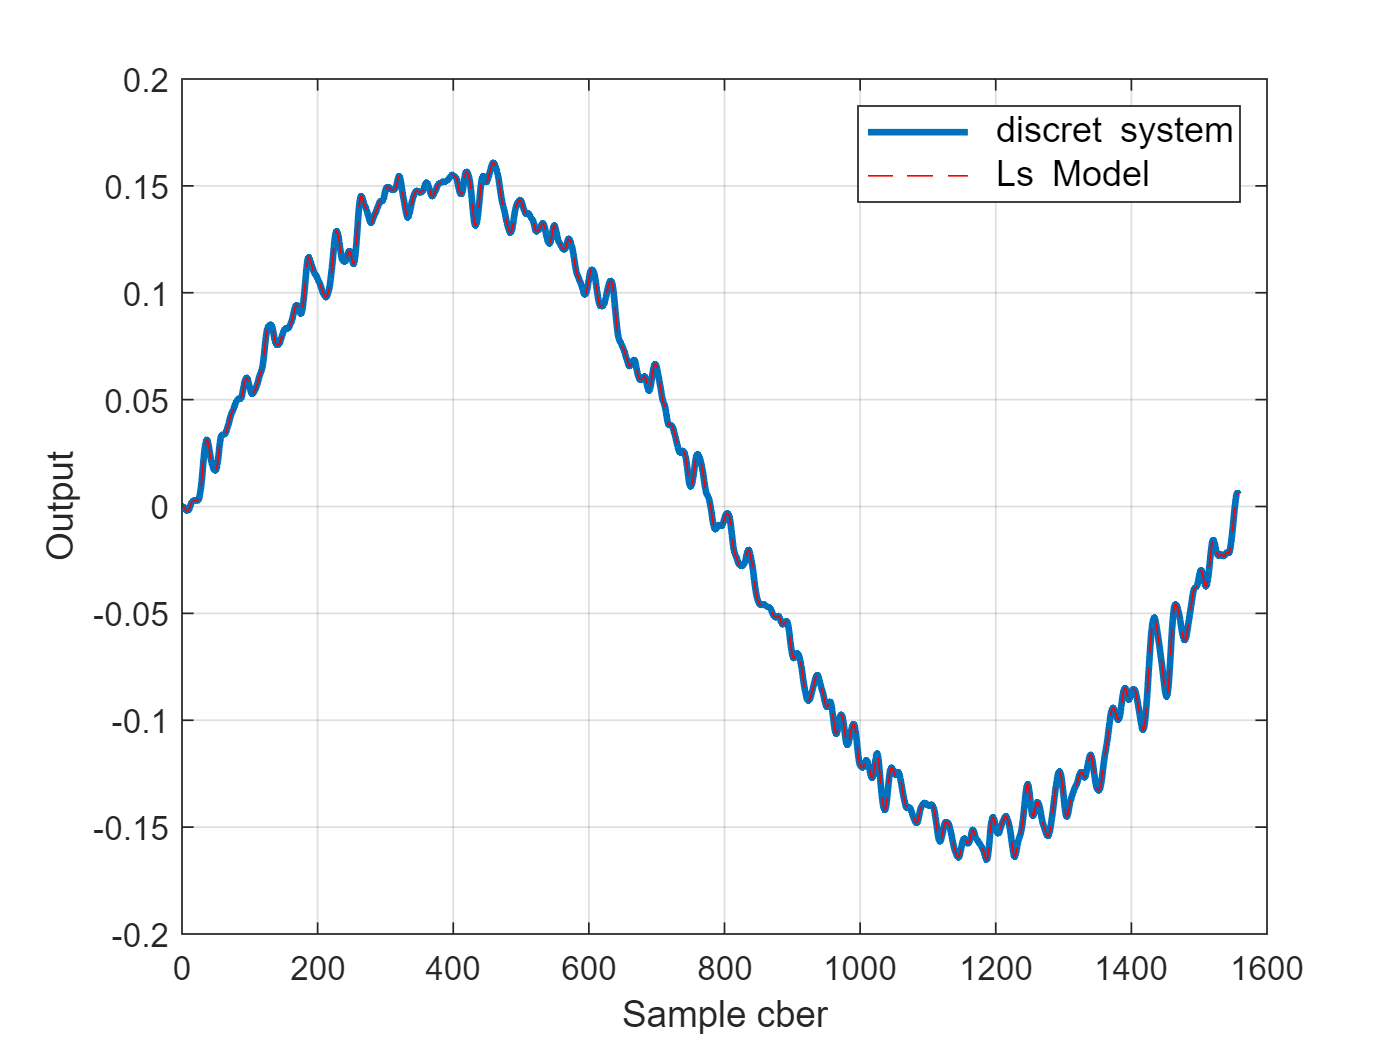

figure
plot(y,'LineWidth',2)
hold on
plot(phi*theta_hat,'r--')
xlabel('Sample cber')
ylabel('Output')
legend('\fontsize{12} discret system','\fontsize{12} Ls Model');
grid on;

### Ploting discret system and Least square Model via step input

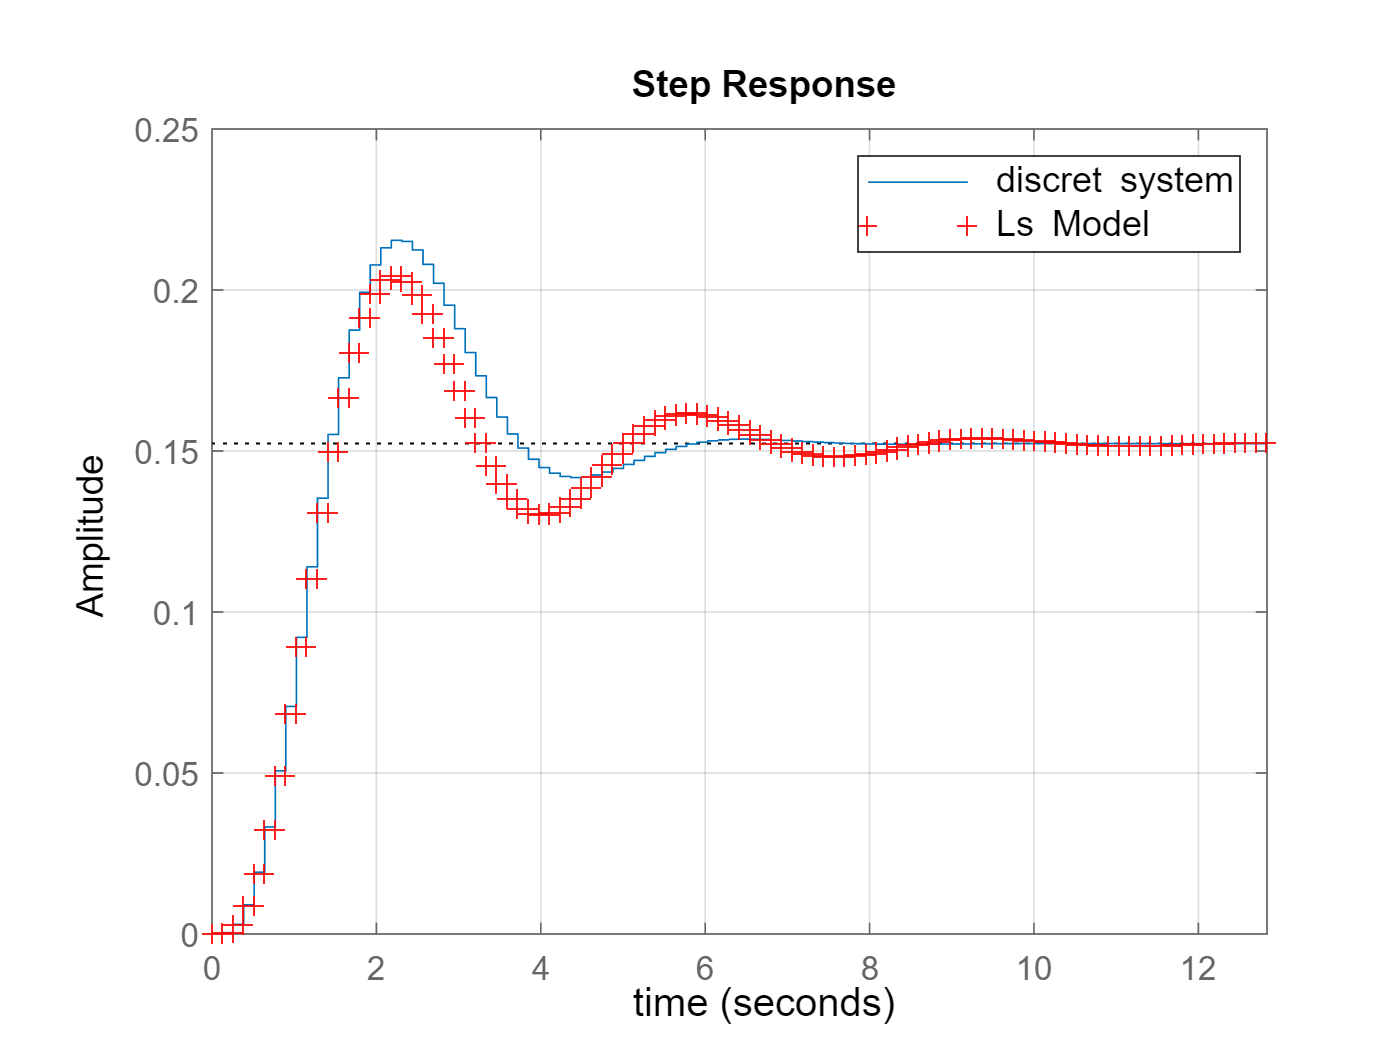

figure
step(sysd,0:T_s:100*T_s)
hold on
step(sysdd,0:T_s:100*T_s,'r+')
legend('\fontsize{12} discret system','\fontsize{12} Ls Model');
grid on;
xlabel('time','fontsize',12);

% ylabel('x2','fontsize',16);
toc

Elapsed time is 4.127999 seconds.
